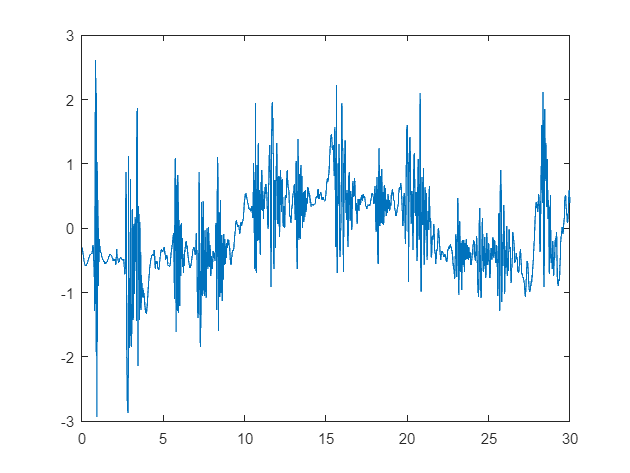

 %Finding the maximums and minimums

    for j = 1 + 150 : length(t) - 150

        %Finding number of time steps spent on one space lattice point

        incoming_velocity = Calculating_Velocity(t, X, j - 50, j + 50, k) ;

        if incoming_velocity == 0 

            d = 10 ;

        else

            d = abs( floor( dx / (incoming_velocity * dt) + uncertanty ) );

        end

        d = 100 ;

        if X(j - d, k) < X(j, k) &&  X(j, k) > X(j + d, k) 

            list_of_maximums(j, k) = t(j) ;

        elseif X(j - d, k) > X(j, k) &&  X(j, k) < X(j + d, k)

            list_of_minimums(j, k) = t(j) ;

        end

    end



    
    %Finding the maximums and minimums

    a_1 = find((X(:,k) > position)) 

    start = a_1(1) ;

    start_time = t(start)

    while start < length(t) - 150

        a_1 = find(abs(X(start : length(t), k) - max(X(start : length(t), k))) < dx * 5) ;

        list_of_maximums(a_1(1) + start, k) = t(a_1(1) + start) ;

        start = start + a_1(1) + uncertanty ;

    end

    list_of_maximums

    start = a_1 ;

    while start < length(t) - 150

        b_1 = find(abs(X(start : length(t), k) - min(X(start : length(t), k))) < dx * 5) ;

        list_of_minimums(b_1(1) + start, k) = t(b_1(1) + start) ;

        start = start + b_1(1) + uncertanty ;

    end

    list_of_minimums